clear
setPath
currentDirectory = pwd
%dataDir = fullfile('', 'data');%dataDir should be directory to data
dataDir = uigetdir();
vidName = 'crabchipsRamp';
vidExtension = '.avi';
testcasename = vidName;
nscales = 1;
norientations = 2;
dsamplefactor = 0.1; %downsample to 0.1 full size

filename = [vidName vidExtension];

vr = VideoReader(fullfile(dataDir, filename));

%if the video is saved with the actual framerate, you can set as follows. 
%samplingrate = vr.FrameRate;

%otherwise, specify the framerate manually
samplingrate = 2200;

wndw = 80;
olap = 40;

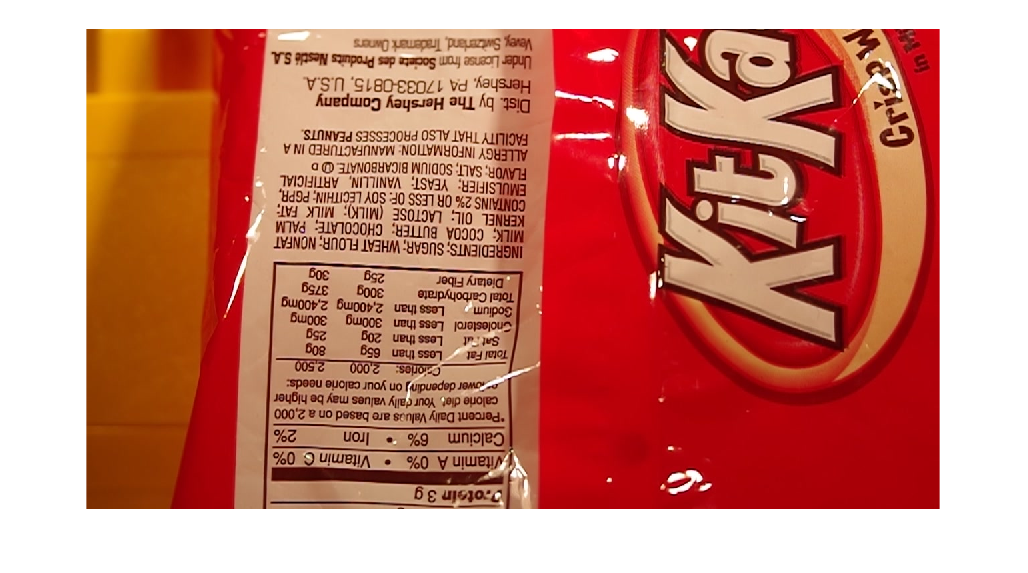

%samplingrate = vr.FrameRate
colorframe = vr.read(1);
imshow(colorframe)

if(dsamplefactor~=1)
    colorframe = imresize(colorframe,dsamplefactor);
end

fullFrame = im2single(squeeze(mean(colorframe,3)));
refFrame = fullFrame;
imshow(fullFrame)

fullFrame

fullFrame = 72×128 single matrix
   74.0000   87.0000  120.0000  135.3333  134.0000  133.6667  131.6667  125.3333  119.0000   99.3333   80.3333   64.0000   56.3333   55.3333   56.6667   60.6667   66.3333   72.0000   75.6667   62.0000   71.6667   73.0000   60.6667   64.6667   68.3333   76.6667  104.0000  175.3333  193.0000  201.3333  210.0000  214.6667  222.0000  205.6667  192.0000  193.0000  191.6667  191.6667  191.6667  190.6667  193.3333  193.0000  192.0000  191.3333  192.0000  192.3333  192.6667  194.0000  193.3333  193.3333
   73.6667   87.0000  114.6667  125.0000  125.3333  125.3333  121.0000  114.0000  107.0000   94.0000   77.3333   63.0000   58.0000   56.6667   55.6667   59.0000   65.3333   71.6667   75.6667   65.3333   59.0000   67.6667   62.3333   64.3333   69.3333   78.0000  101.6667  176.3333  199.3333  224.6667  230.0000  233.0000  231.0000  199.6667  196.3333  196.6667  193.3333  192.6667  192.6667  190.0000  165.0000  163.6667  161.3333  159.6667  158.0000  172.6667  170.

size(fullFrame)

ans =     72   128


[pyrRef, pind] = buildSCFpyr(fullFrame, 2, 2);
size(pyrRef)

ans =        44352           1


size(pind)

ans =      8     2


pind

pind =     72   128
    72   128
    72   128
    72   128
    36    64
    36    64
    36    64
    18    32


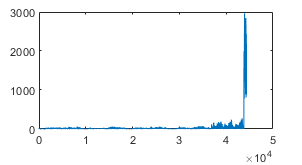

plot(abs(pyrRef));

imdft = fftshift(fft2(fullFrame))

imdft = 72×128 single matrix
	1.0e+05 *

  -0.0004 + 0.0000i   0.0021 - 0.0002i   0.0029 + 0.0002i  -0.0029 + 0.0018i   0.0040 + 0.0031i  -0.0026 + 0.0011i  -0.0032 + 0.0032i  -0.0009 - 0.0043i  -0.0030 + 0.0009i  -0.0003 - 0.0016i  -0.0005 - 0.0030i   0.0014 - 0.0015i  -0.0013 + 0.0011i   0.0036 - 0.0040i   0.0015 + 0.0011i  -0.0012 + 0.0040i   0.0004 - 0.0085i   0.0068 + 0.0055i   0.0020 + 0.0022i  -0.0093 + 0.0005i   0.0038 + 0.0004i   0.0041 + 0.0023i  -0.0032 + 0.0018i  -0.0069 - 0.0058i   0.0051 + 0.0017i  -0.0004 + 0.0041i  -0.0019 - 0.0075i   0.0060 - 0.0009i   0.0012 + 0.0084i  -0.0060 + 0.0004i   0.0036 - 0.0041i  -0.0012 + 0.0023i  -0.0067 + 0.0060i   0.0002 - 0.0092i   0.0047 - 0.0060i   0.0040 + 0.0080i  -0.0030 - 0.0004i  -0.0016 + 0.0072i  -0.0056 - 0.0031i  -0.0049 - 0.0045i   0.0066 - 0.0085i   0.0009 + 0.0072i  -0.0010 + 0.0005i  -0.0044 - 0.0017i   0.0016 - 0.0041i   0.0028 + 0.0071i  -0.0132 - 0.0071i   0.0123 - 0.0148i   0.0112 + 0.0014i   0.0061 + 0.0113i
   0.002

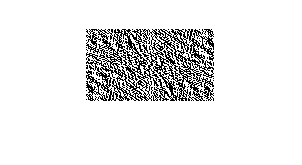

imshow(imdft)